MATLAB Homework 2

Lecturer: Mokshin V.V.

Student: Galimov M.D.

Group № 4167

Kazan, 2019 

**Problem 1. **Draw a line plot that shows the Gaussian probability distribution with mean 50 and standard deviation 10. Label the axes.

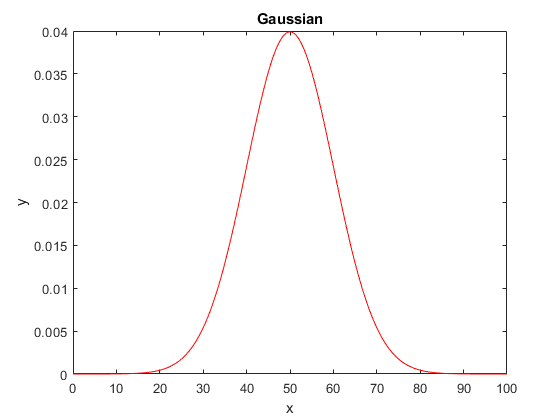

x = [0:.1:100];
y = normpdf(x,50,10);
figure;
plot(x,y, 'r')
xlabel('x');
ylabel('y');
title('Gaussian');

**Problem 2. **The`data1` variable in Homework2.mat is a matrix of dimensions 3 x 20. Each row contains measurements obtained for a distinct group of subjects. We are interested in assessing whether there are any differences across the three groups. The metric that we will use is variability in the group means (i.e. compute the mean of each group and then compute the standard deviation across the three mean values). If this variability is high, that would suggest that the groups are different, whereas if the variability is low, that would suggest that the groups are the same. Use randomization to test the null hypothesis that all three groups come from the same underlying distribution. Run 10,000 simulations and calculate a one-tailed *p*-value. Echo the computed *p*-value to the screen.

actualval = std(mean(data1,2));
alldata = data1(:);
vals = zeros(1,10000);
for p=1:10000
    datashuffle = alldata(randperm(length(alldata)));
    datashuffle = reshape(datashuffle,[3 20]);
    vals(p) = std(mean(datashuffle,2));
end
pval = sum(vals > actualval) / 10000;
pval

pval = 0.0121

**Problem 3. **Suppose we measure a group of 100 subjects before and after a certain manipulation. The `data2a`variable in Homework2.mat is a vector of dimensions 1 x 100 with the pre-manipulation measurement, and the `data2b `variable in Homework2.mat is a vector of dimensions 1 x 100 with the post-manipulation measurement. Quantify the manipulation effect by subtracting the pre-manipulation from the post-manipulation measurement. Then use bootstrapping to test the null hypothesis that the differences come from a probability distribution with mean 0. Run 10,000 simulations and calculate a two-tailed *p*-value. Echo the computed *p*-value to the screen.

% compute the difference between the post- and pre-manipulation measurements
x = data2b - data2a;
%actial mean of data
actualval = mean(x);
% centering x
xcentered = x - mean(x);
vals = zeros(1,10000);
for p=1:10000
 % create bootstrap indices
 ix = ceil(length(xcentered)*rand(1,length(xcentered)));
 % record the result got from boostrapped sample
 vals(p) = mean(xcentered(ix)); 
end
pval = sum(abs(vals) > abs(actualval)) / 10000;
pval

pval = 0.0408

**Problem 4. **Flip a coin *n* times and count the number of heads obtained. Repeat this 10,000 times and visualize thedistribution of results using a histogram. Perform this simulation for different *n* values (*n* = 10, 100, 1000) and show the resulting histograms on three different subplots of a single figure. For each subplot, label its axes and provide a title.

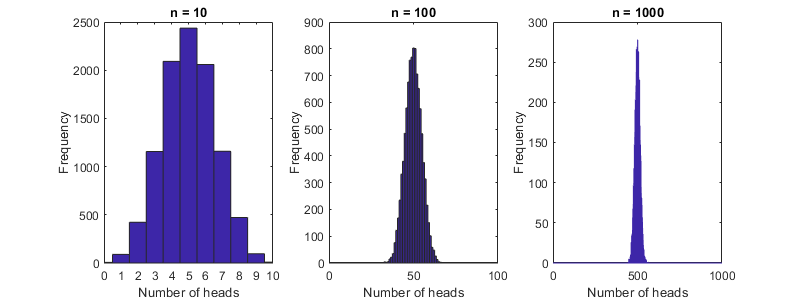

% define number of coin flips
ns = [10 100 1000];
% create a new figure and resize it
figure;
set(gcf,'Position',[100 100 800 300]);
% loop over number of coin flips
for p=1:length(ns)
    % perform 10000 simulations of random coin flips
    flips = round(rand(10000,ns(p)));
    % count number of heads in each simulation
    dist = sum(flips==0,2);
    % initalize subplot
    subplot(1,length(ns),p);
    % plot histogram with bin centers at each possible number of heads
    hist(dist,0:1:ns(p));
    ax = axis;
    axis([0 ns(p) ax(3:4)]);
    xlabel('Number of heads');
    ylabel('Frequency');
    title(sprintf('n = %d',ns(p)));
end